% ============================
% INVERSE KINEMATICS FOR YOUR ROBOT
% ============================

clc;
clear;
close all;

% Load Robotics Toolbox (Peter Corke)
% Make sure the Robotics Toolbox is installed and added to your MATLAB path

% --- Define Links using MODIFIED DH parameters
L(1) = Link('d', 60, 'a', 3, 'alpha', deg2rad(90));%, 'modified');
L(2) = Link('d', 0,  'a', 85, 'alpha', deg2rad(0));%,  'modified');
L(3) = Link('d', -43, 'a', 0,  'alpha', deg2rad(90));%, 'modified');
L(4) = Link('d', 82, 'a', 3,  'alpha', deg2rad(90));%, 'modified');
L(5) = Link('d', 20, 'a', 10, 'alpha', deg2rad(90));%, 'modified');
L(6) = Link('d', 26, 'a', 0,  'alpha', deg2rad(0));%, 'modified');

% --- Create the SerialLink robot
robot = SerialLink(L, 'name', 'My6DOFRobot');

% --- Plot the robot in zero position
figure(1);
robot.plot([pi/2 pi/2 pi/2 pi/2 pi pi]);
title('Robot Initial Configuration');

% ============================
% Define Desired End-Effector Pose
% ============================

% Example: desired position (x, y, z) in mm
% and orientation (roll, pitch, yaw) in radians
x = 60;  % mm
y = 60;  % mm
z = 100;  % mm

roll = 5*(pi/180);        % rad
pitch = 63*(pi/180);    % rad
yaw = 127*(pi/180);         % rad

% Create the transformation matrix
T_desired = transl(x, y, z) * rpy2tr(roll, pitch, yaw);

disp('Desired End-Effector Pose:');

Desired End-Effector Pose:


disp(T_desired);

    0.9991   -0.0386    0.0192   60.0000
    0.0387    0.9993   -0.0008   60.0000
   -0.0192    0.0015    0.9998  100.0000
         0         0         0    1.0000




% ============================
% Inverse Kinematics Solution
% ============================

% Solve inverse kinematics numerically
% Use mask [1 1 1 1 1 1] for full 6D pose (position + orientation)
% Provide an initial guess if needed
initial_guess = [0 pi/2 pi/2 0 0 0];

q_solution = robot.ikine(T_desired, initial_guess, 'mask', [pi/4 pi/4 -pi/2 0 0 0]);

disp('Inverse Kinematics Joint Angles (in radians):');

Inverse Kinematics Joint Angles (in radians):


disp(q_solution);

   -0.0528    1.3361   -0.7634   -0.0150   -0.2686         0



disp('Inverse Kinematics Joint Angles (in degrees):');

Inverse Kinematics Joint Angles (in degrees):


disp(rad2deg(q_solution));

   -3.0262   76.5548  -43.7422   -0.8602  -15.3913         0




disp('Inverse Kinematics Joint Angles for our Setup (in degrees):');

Inverse Kinematics Joint Angles for our Setup (in degrees):


our_q = rad2deg(q_solution) + [0 0 0 0 -90 -90];
disp(our_q);

   -3.0262   76.5548  -43.7422   -0.8602 -105.3913  -90.0000





% ============================
% Verify Solution
% ============================

% Compute forward kinematics with the solution
%% 
T_actual = robot.fkine(q_solution);

disp('Actual End-Effector Pose from FK:');

Actual End-Effector Pose from FK:


disp(T_actual);

      0.6662   0.04019   -0.7447        60
    -0.02073    0.9992   0.03538        60
      0.7455 -0.008135    0.6665       100
           0         0         0         1


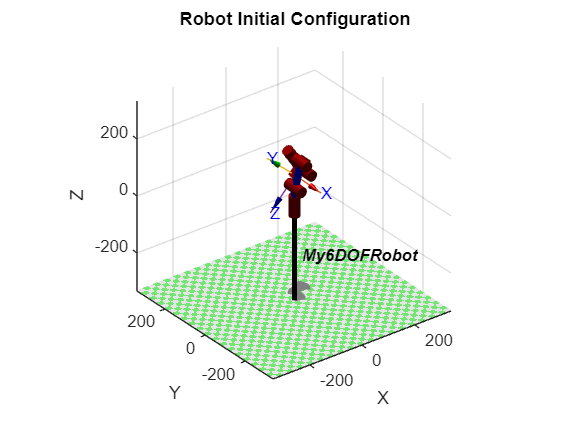


% Plot robot in the computed configuration with our constraints
figure(2);
robot.plot(deg2rad(our_q));

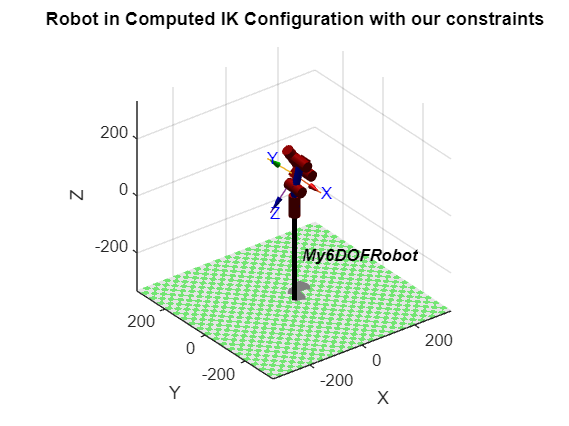

title('Robot in Computed IK Configuration with our constraints')